clc;
clear;

load("SegmentationValues.mat")
fs = 1000;
N = length(Systole{2})

N = 400

s_length = N/fs;
t = linspace(0, N/fs, N)

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0201    0.0211    0.0221    0.0231    0.0241    0.0251    0.0261    0.0271    0.0281    0.0291    0.0301    0.0311    0.0321    0.0331    0.0341    0.0351    0.0361    0.0371    0.0381    0.0391    0.0401    0.0411    0.0421    0.0431    0.0441    0.0451    0.0461    0.0471    0.0481    0.0491


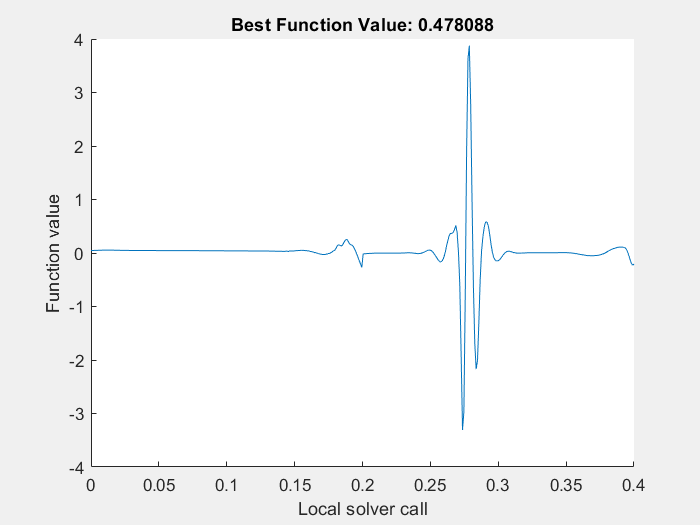

plot(t,Systole{2})

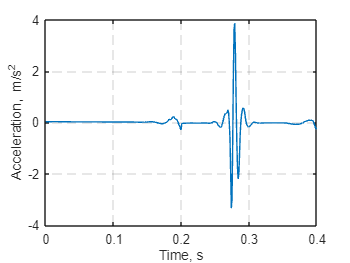

shock = acc([t',Systole{2}']);  %First column time and the second data
shock = shock.detrend('constant');
shock = shock.getsampleusingtime(0, 1000);
shock = shock.resample1(numel(t));
shock.plot;

      ErrTol: 0.1000
    FreSpace: 2
      IniTim: 0
       MinSW: 6
      PhiNum: 2
      TauLoc: [1×3 double]
      TwoWay: 0
      XiList: [1×4 double]

     1

144 local solver will run in each interation.
MultiStart completed some of the runs from the start points.

109 out of 144 local solver runs converged with a positive local solver exit flag.
    0.9381

     2

144 local solver will run in each interation.
MultiStart completed some of the runs from the start points.

126 out of 144 local solver runs converged with a positive local solver exit flag.
    0.9381    0.9579

     3

144 local solver will run in each interation.
MultiStart completed some of the runs from the start points.

123 out of 144 local solver runs converged with a positive local solver exit flag.
  Columns 1 through 2

    0.9381    0.9579

  Column 3

    0.9765

     4

144 local solver will run in each interation.
MultiStart completed some of the runs from the start points.

117 out of 144 local solver 

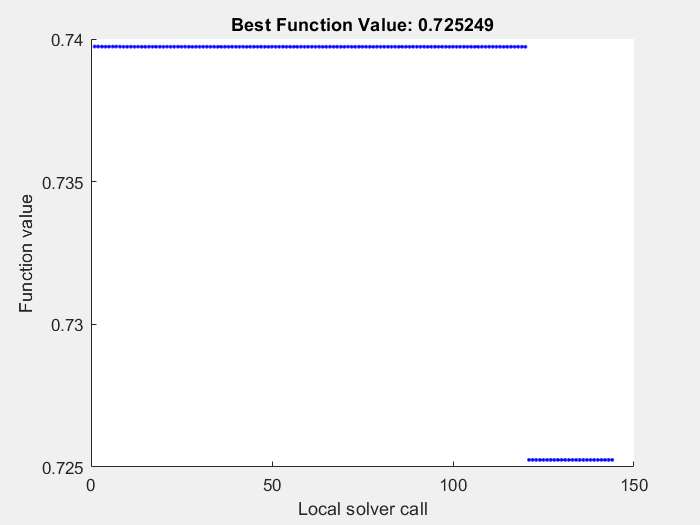

MultiStart completed some of the runs from the start points.

132 out of 144 local solver runs converged with a positive local solver exit flag.
  Columns 1 through 2

    0.9381    0.9579

  Columns 3 through 4

    0.9765    0.9827

  Columns 5 through 6

    0.9879    0.9912



results = shock.fit; %returns the object of shock waveform

tab = results.table;

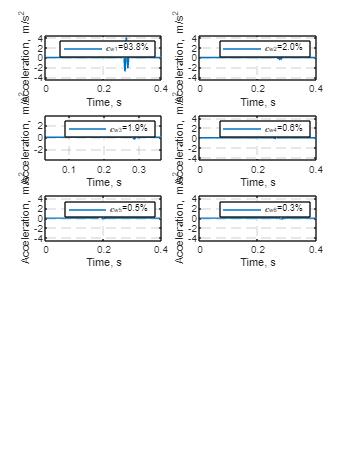

results.subplot;

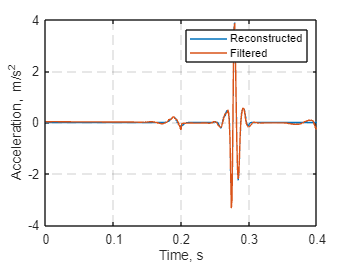

hold off

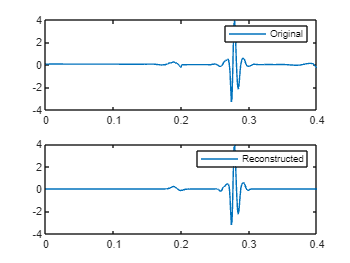


%Plotting 3 subplots of original, filtered and reconstructed signal
subplot(2,1,1)
plot(t,Systole{2})
legend('Original')

reconstructed = results.yhat;
subplot(2,1,2)
plot(reconstructed.Time,reconstructed.Data)
legend('Reconstructed')

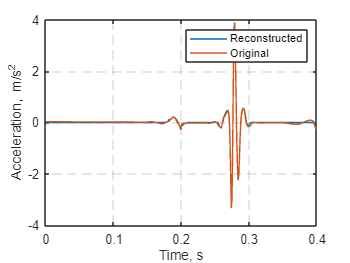

%Plotting Reconstructed and Filtered signals on one graph
reconstructed = results.yhat;
reconstructed.plot;
hold on;
plot(shock.Time, shock.Data);
legend('Reconstructed', 'Original');